# Segment Analyze for Well Trained Day

close all;clear;clc;
[M1, mPFC, ratios, eventTrain, M1num, mPFCnum, actTrain, segTrain, segRatios] = spikeTime2Train("data/rat_010_07_04.mat");
fprintf(['M1withSpike=%0.4f\nmPFCwithSpike=%0.4f\nM1multiSpike=%0.4f\n' ...
  'mPFCmultiSpike=%0.4f'], ratios)

M1withSpike=0.1314
mPFCwithSpike=0.0976
M1multiSpike=0.0499
mPFCmultiSpike=0.0402

fprintf(['M1withSpike=%0.4f\nmPFCwithSpike=%0.4f\nM1multiSpike=%0.4f\n' ...
  'mPFCmultiSpike=%0.4f'], segRatios)

M1withSpike=0.1403
mPFCwithSpike=0.0962
M1multiSpike=0.0547
mPFCmultiSpike=0.0392

sum(eventTrain)

ans = 37675

sum(segTrain)

ans = 50635

successCount = 0;
spikeLength = length(eventTrain);
for i=2:spikeLength
  if (eventTrain(i-1) == 1 && eventTrain(i) == 0)
    successCount = successCount + 1;
  end
end
successCount

successCount = 180

responseTime = zeros(1,successCount);
trailNum = 1;
for i=2:spikeLength
  if (eventTrain(i-1) == 1 && eventTrain(i) == 0)
    trailNum = trailNum + 1;
  end
  if (eventTrain(i) == 1)
    responseTime(trailNum) = responseTime(trailNum) + 1;
  end
end
responseTime = responseTime/100;

舍去长于5s的

trailTooLong = find(responseTime>5);
eventTrainRow = eventTrain;
trailNum = 0;
for i=2:spikeLength
  if (eventTrainRow(i-1) == 0 && eventTrainRow(i) == 1)
    trailNum = trailNum + 1;
  end
  if (eventTrainRow(i) == 1 && ismember(trailNum, trailTooLong))
    eventTrain(i) = 0;
    segTrain(i) = 0;
  end
end

sum(eventTrain)

ans = 34666

sum(segTrain)

ans = 49945

successCountRow = successCount;
successCount = 0;
for i=2:spikeLength
  if (eventTrain(i-1) == 1 && eventTrain(i) == 0)
    successCount = successCount + 1;
  end
end
successCount

successCount = 175

responseTimeRow = responseTime;
responseTime = zeros(1,successCount);
trailNum = 1;
for i=2:spikeLength
  if (eventTrain(i-1) == 1 && eventTrain(i) == 0)
    trailNum = trailNum + 1;
  end
  if (eventTrain(i) == 1)
    responseTime(trailNum) = responseTime(trailNum) + 1;
  end
end
responseTime = responseTime/100;

## plot

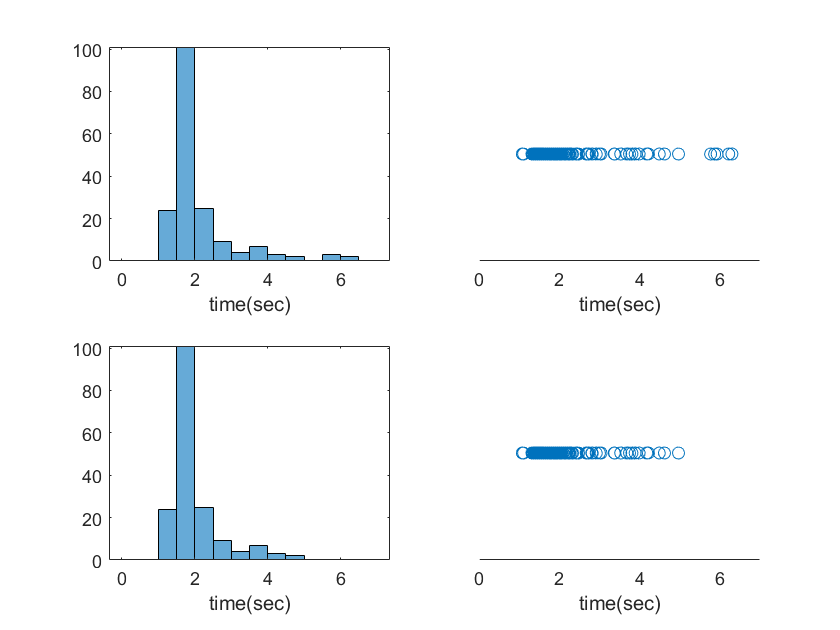

figure
subplot(2,2,1)
histogram(responseTimeRow, [0 0.5 1 1.5 2 2.5 3 3.5 4 4.5 5 5.5 6 6.5 7])
xlabel("time(sec)")
subplot(2,2,3)
histogram(responseTime, [0 0.5 1 1.5 2 2.5 3 3.5 4 4.5 5 5.5 6 6.5 7])
xlabel("time(sec)")
subplot(2,2,2)
scatter(responseTimeRow,zeros(1,successCountRow))
xlabel("time(sec)")
xlim([0,7])
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca,'YColor','white')
subplot(2,2,4)
scatter(responseTime,zeros(1,successCount))
xlabel("time(sec)")
xlim([0,7])
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca,'YColor','white')

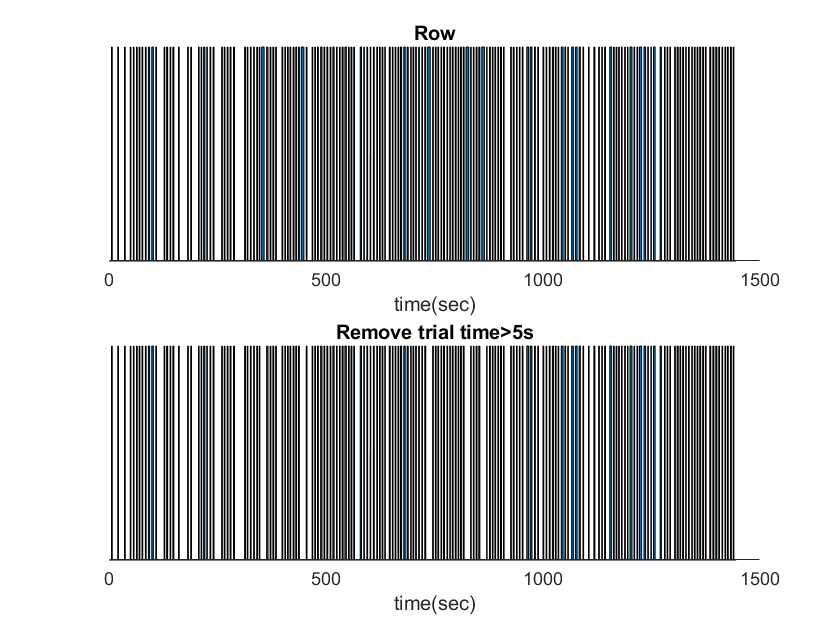

figure
subplot(2,1,1)
spikeLengthRow = length(eventTrainRow);
area(0.01:0.01:spikeLengthRow*0.01, eventTrainRow)
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")
title('Row')
subplot(2,1,2)
spikeLength = length(eventTrain);
area(0.01:0.01:spikeLength*0.01, eventTrain)
set(gca, 'TickLength', [0 0])
set(gca, 'ytick', [])
set(gca, 'box', 'off')
set(gca, 'YColor', 'white')
xlabel("time(sec)")
title('Remove trial time>5s')

## delay

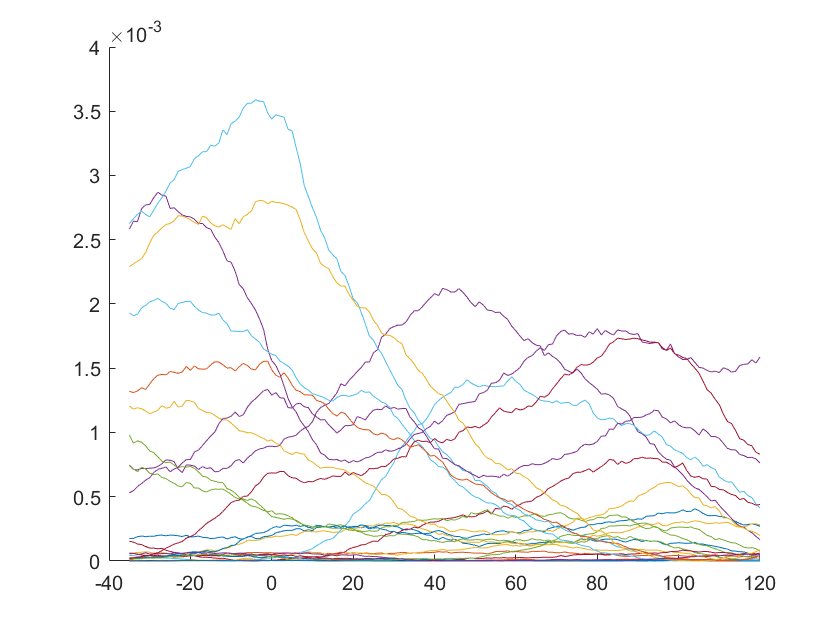

M1delayMI   = zeros(M1num, 156);
for delay=-35:120 % delay vary from 0ms~700ms
  M1delayMI(:,delay+1+35) = mutualInformation(M1(1+120:end-delay-120,:), actTrain(delay+1+120:end-120)');
end
figure
hold on
for i=1:M1num
  plot(-35:120, M1delayMI(i,:))
end
hold off

挑出大的几条曲线（存在令mi>2e-3的delay）

goodM1 = [];
for i=1:M1num
  if (sum(M1delayMI(i,35:end)>1.5e-3)>=1)
    goodM1 = [goodM1, i];
  end
end
goodM1

goodM1 =      4    11    13    20    21    23    24


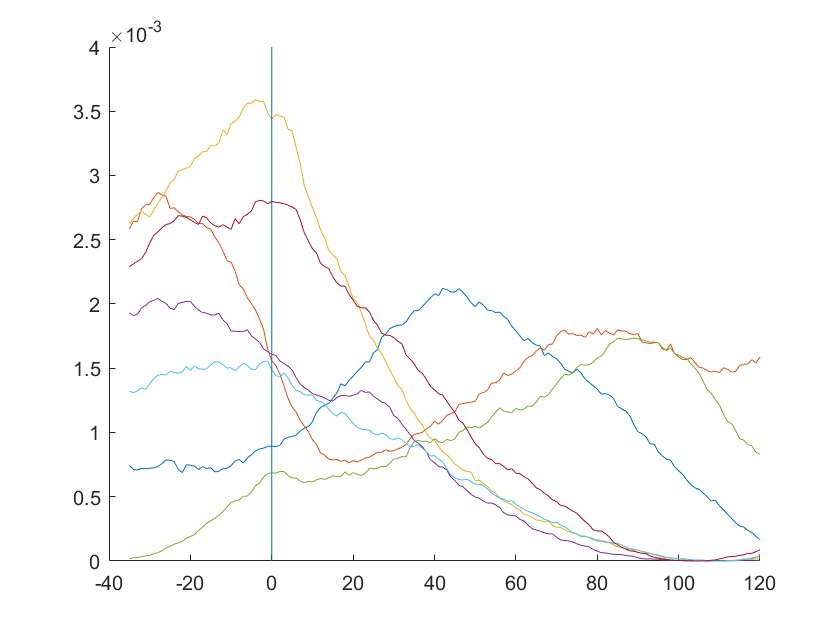

figure
hold on
for i=1:length(goodM1)
  plot(-35:120, M1delayMI(goodM1(i),:))
end
plot([0,0], [0,4e-3])
hold off

有点问题。。。怎么会有负的delay呢orz

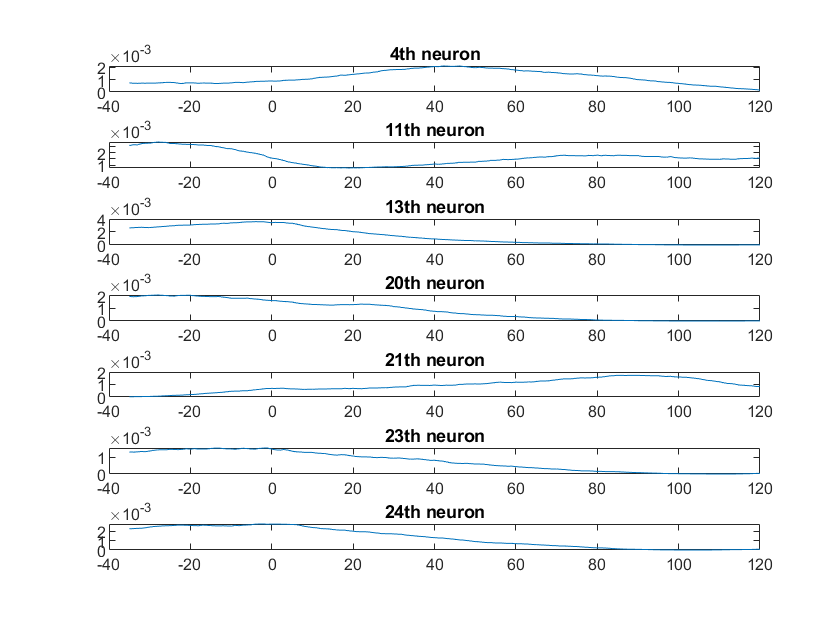

figure
for i=1:length(goodM1)
  subplot(length(goodM1), 1, i)
  plot(-35:120, M1delayMI(goodM1(i),:))
  title ([num2str(goodM1(i)), 'th neuron'])
end

critical day选的7，2，3对应过来可能是 8/9，3，4

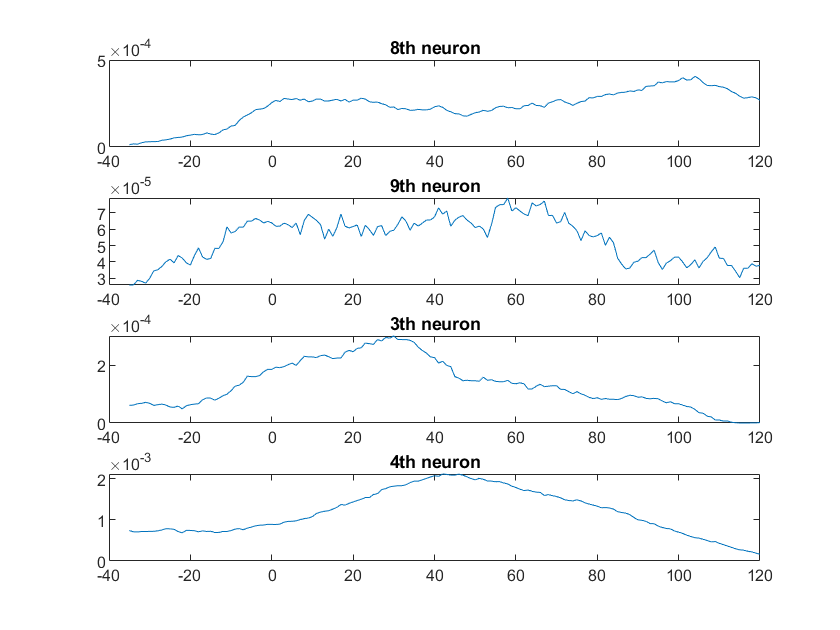

figure
subplot(4,1,1)
plot(-35:120, M1delayMI(8,:))
title ('8th neuron')
subplot(4,1,2)
plot(-35:120, M1delayMI(9,:))
title ('9th neuron')
subplot(4,1,3)
plot(-35:120, M1delayMI(3,:))
title ('3th neuron')
subplot(4,1,4)
plot(-35:120, M1delayMI(4,:))
title ('4th neuron')

看起来8，3，4很可能是critical day里的7，2，3

最终选8，3，4，21吧

mPFC与M1

M1=8

mPFCdelayMI = zeros(mPFCnum, 156);
for delay=-35:120
  mPFCdelayMI(:,delay+1+35) = mutualInformation(mPFC(1+120:end-delay-120,:), M1(delay+1+120:end-120,8));
end

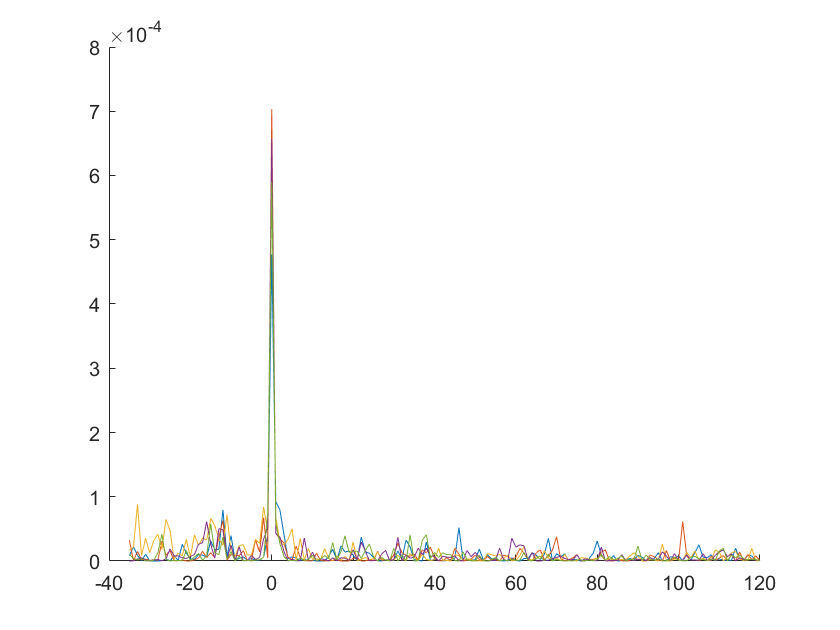

goodmPFC = [];
goodmPFCmi = [];
figure
hold on
for i=1:mPFCnum
  if (sum(mPFCdelayMI(i,:)>4.7e-4))
      goodmPFC = [goodmPFC,i];
      goodmPFCmi = [goodmPFCmi,max(mPFCdelayMI(i,:))];
    plot(-35:120, mPFCdelayMI(i,:))
  end
end
hold off

goodmPFC

goodmPFC =     10    11    12    14    20


goodmPFCmi

goodmPFCmi = 	1.0e+-3 *

    0.4769    0.7032    0.5977    0.6566    0.5904


M1=3

mPFCdelayMI = zeros(mPFCnum, 156);
for delay=-35:120
  mPFCdelayMI(:,delay+1+35) = mutualInformation(mPFC(1+120:end-delay-120,:), M1(delay+1+120:end-120,3));
end

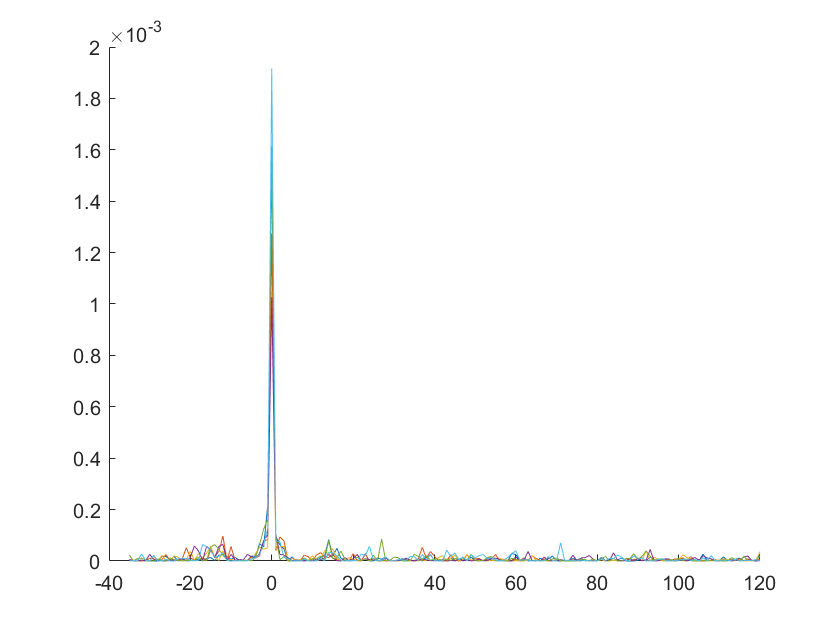

goodmPFC = [];
goodmPFCmi = [];
figure
hold on
for i=1:mPFCnum
  if (sum(mPFCdelayMI(i,:)>10e-4))
      goodmPFC = [goodmPFC,i];
      goodmPFCmi = [goodmPFCmi,max(mPFCdelayMI(i,:))];
    plot(-35:120, mPFCdelayMI(i,:))
  end
end
hold off

goodmPFC

goodmPFC =      6    10    11    12    14    20


goodmPFCmi*100

ans =     0.1558    0.1274    0.1050    0.1026    0.1613    0.1916


M1=4

mPFCdelayMI = zeros(mPFCnum, 156);
for delay=-35:120
  mPFCdelayMI(:,delay+1+35) = mutualInformation(mPFC(1+120:end-delay-120,:), M1(delay+1+120:end-120,4));
end

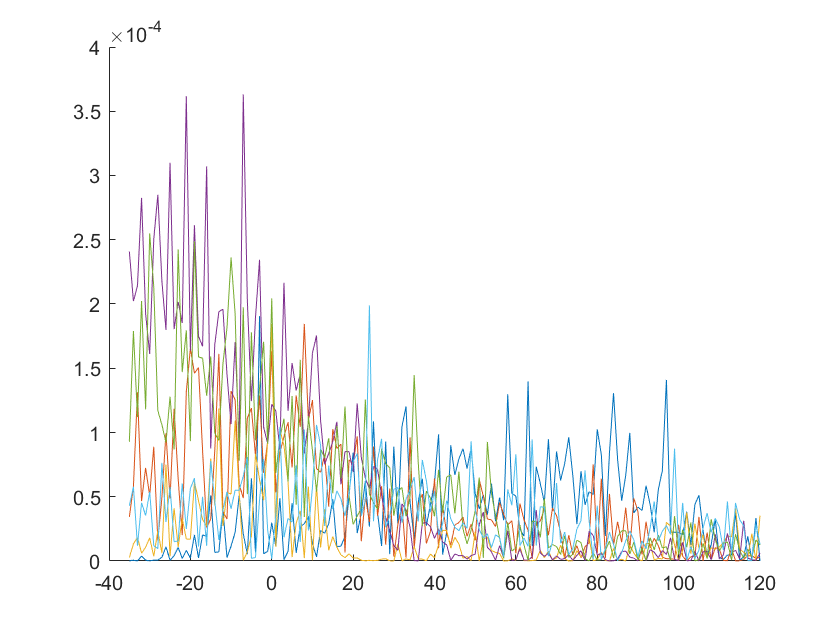

goodmPFC = [];
goodmPFCmi = [];
figure
hold on
for i=1:mPFCnum
  if (sum(mPFCdelayMI(i,:)>1.5e-4))
      goodmPFC = [goodmPFC,i];
      goodmPFCmi = [goodmPFCmi,max(mPFCdelayMI(i,:))];
    plot(-35:120, mPFCdelayMI(i,:))
  end
end
hold off

goodmPFC

goodmPFC =      4    12    14    16    17    22


goodmPFCmi

goodmPFCmi = 	1.0e+-3 *

    0.1906    0.1845    0.1845    0.3632    0.2550    0.1989


这。。。。怕不是没有时延。。或者干脆没有关系？

M1=21

mPFCdelayMI = zeros(mPFCnum, 156);
for delay=-35:120
  mPFCdelayMI(:,delay+1+35) = mutualInformation(mPFC(1+120:end-delay-120,:), M1(delay+1+120:end-120,21));
end

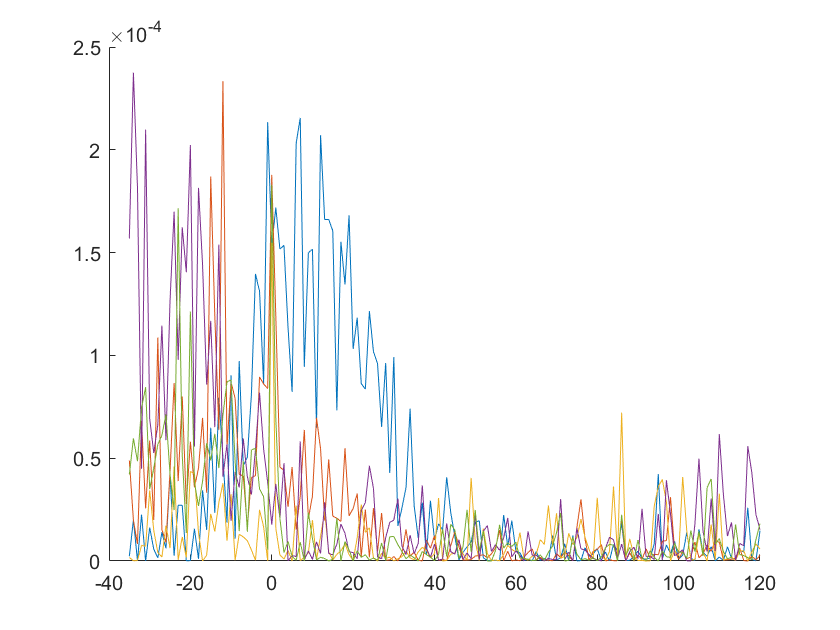

goodmPFC = [];
goodmPFCmi = [];
figure
hold on
for i=1:mPFCnum
  if (sum(mPFCdelayMI(i,:)>1.5e-4))
      goodmPFC = [goodmPFC,i];
      goodmPFCmi = [goodmPFCmi,max(mPFCdelayMI(i,:))];
    plot(-35:120, mPFCdelayMI(i,:))
  end
end
hold off

goodmPFC

goodmPFC =      4    12    14    16    17


goodmPFCmi

goodmPFCmi = 	1.0e+-3 *

    0.2155    0.2334    0.1547    0.2376    0.1830


猜测同上

最终试一下M1对应8和3，mPFC无延时，分别导出两个数据文件

save some results

M1neurons   = 8;
mPFCneurons = [10,11,12,14,20];
recordRange = 1:144200;
M1spike = M1(recordRange, M1neurons);
mPFCspike = mPFC(recordRange, mPFCneurons);
eventTrain = eventTrain(recordRange);
segTrain = segTrain(recordRange);
optimalDelay = 104;
save("data/rat_010_07_04_spike_train_selected_with_delay_8.mat", "M1spike", "mPFCspike", "eventTrain", "optimalDelay", "segTrain")
M1neurons   = 3;
mPFCneurons = [6,10,11,14,20];
M1spike = M1(recordRange, M1neurons);
mPFCspike = mPFC(recordRange, mPFCneurons);
eventTrain = eventTrain(recordRange);
segTrain = segTrain(recordRange);
optimalDelay = 30; % find(M1delayMI(3,:)==max(M1delayMI(3,:)))-1-35
save("data/rat_010_07_04_spike_train_selected_with_delay_3.mat", "M1spike", "mPFCspike", "eventTrain", "optimalDelay", "segTrain")